# Antenna Design Using the Antenna Designer App

Begin by opening up the Antenna Designer App from the APPS tab.

The first step is to select your type of radiation. In this tutorial we will use an Omnidirectional radiation.

So select *OmniDirectional *from the *Radiation *menu in the top left corner of the toolbar.

This will grey out all antennas which are not omnidirectional. For this example we will be using the *invertedFcoplanar *antenna from the patch family of antennas. Select it from the drop down menu of the list of antennas.

We are going to design an antenna which operates at the 2.4GHz range.

This is a range commonly used by Wifi, cellular, and microwaves.

To select this frequency type 2400 in the box below *Design Frequency. *Ensure it is in MHz.

Then click the green checkmark labelled *Accept*. 

The antenna model will now be scaled to resonate at that frequency.

To verify that it does resonate with that frequency, click on *Impedance *in the *VECTOR FREQUENCY ANALYSIS *tab in the top toolbar.

Note that PEC stands for perfect electrical conductor.

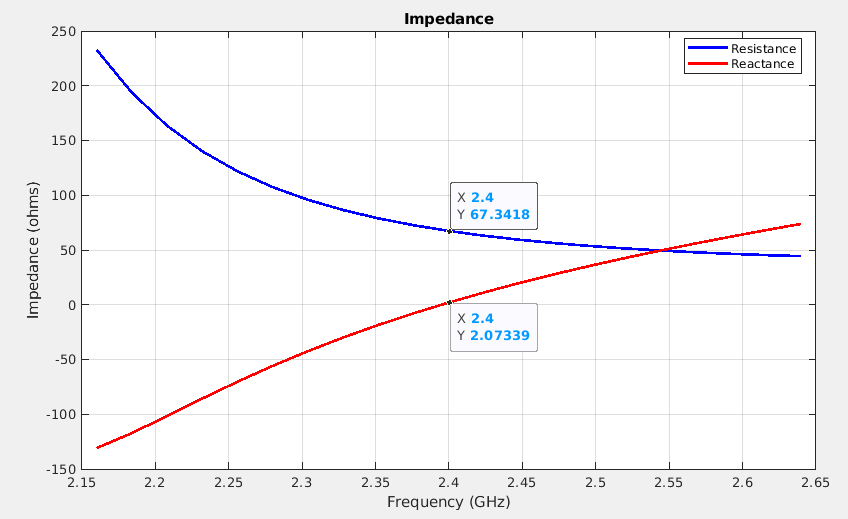

As we can see the reactance is quite low and the resistance is about 70 ohms.

Another parameter we can use to judge the performance of the antenna is the *S Parameter*. This button should be to the right of *Impedance*.

The S Parameter is the reflection coefficient in dB.

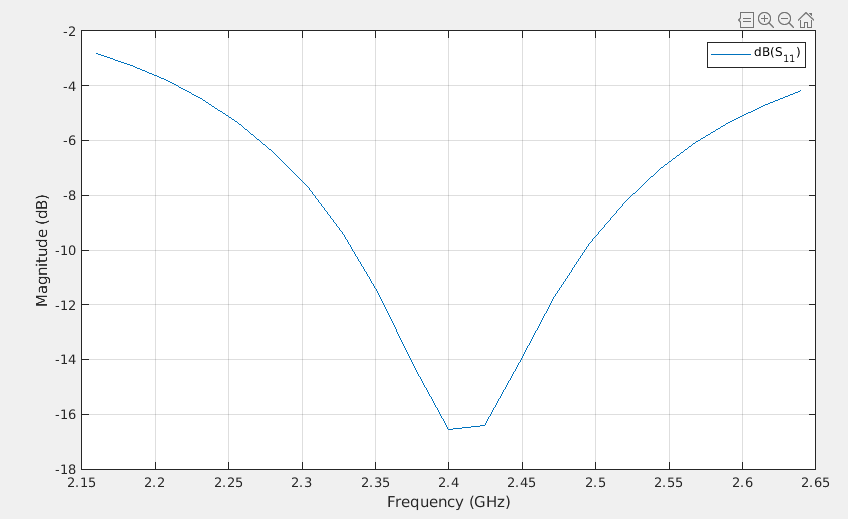

From this graph we see how the reflection coefficient changes with frequency.

In RF applications we use the -10dB mark instead of the -3dB mark since -10dB indicates 90% of power is transfered, whereas the -3dB means 50% is transfered. 50% is too low for low power applications. -10dB indicates that it is well matched.

Each division on the graph is 50MHz. So the bandwidth at the -10dB mark is about 3 divisions, 150MHz.

150e6 / 2.4e9 % 150MHz/2.4GHz = 0.0625

ans = 0.0625

This results in approximately 6% of bandwidth.

Another parameter we can analyze is the Current Distribution. This can be found just to the right of *S Parameter *labelled *Current*.

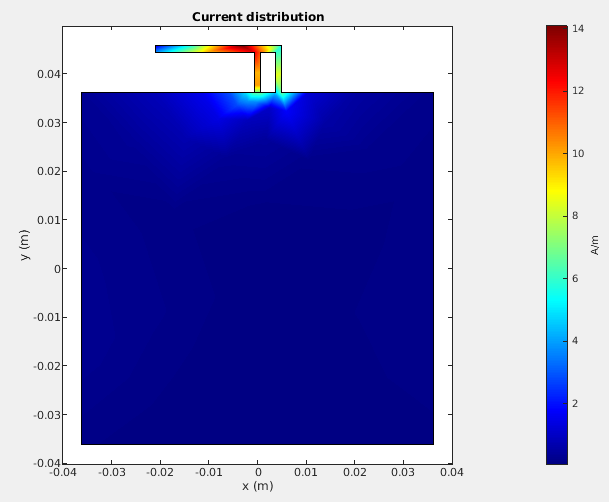

This is technically a quarter-wave monoplane antenna just bent over. The large square portion would be the ground plane. Red indicates higher currents, blue indicates lower currents.

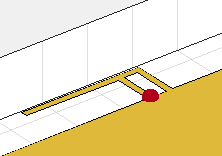         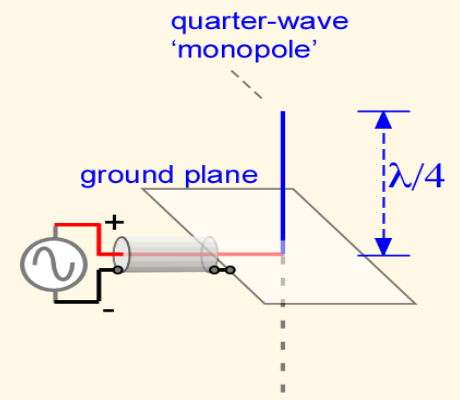

The red sphere indicates where the signal is fed from. So to further expand on the monopole comparision, the feeder acts as the AC source.

At the bottom of the F (left most area there is practically a ground). In the center there is the most current. The top leg of the F is a short to the ground plane that helps with impedance matching.

We can also view the 3D radiation pattern of the antenna using the *3D Pattern* tool just to the left of *Current Distribution.*

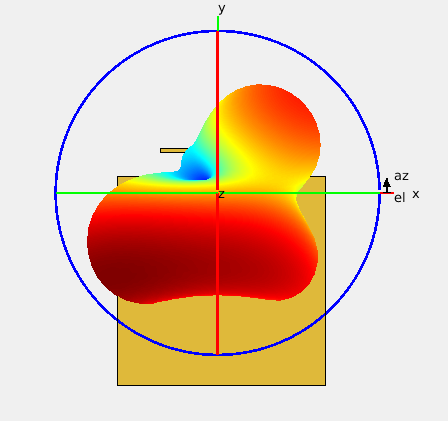

Taking a birds eye view we see the donut shape of the radiation pattern has a lump around the grounded top leg of the F. This radiation pattern is a model of a perfect antenna not subject to any losses. This lump will be notably smaller as we continue our analysis.

So far we have not incorporated the antenna into a PCB. To begin modelling the effects of adding this antenna on a PCB we can export the antenna to a script. To do this click *Export > Export as script *in the top toolbar.

Below is similar to the output that was generated with only a few changes to make the code more portable to other applications.

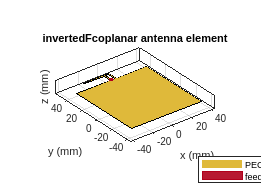

% Create a invertedFcoplanar antenna
% Generated by MATLAB(R) 9.13 and Antenna Toolbox 5.3.
% Generated on: 26-Jan-2023 03:07:05

%% Antenna Properties 

F0 = 2.4e9;

antennaObject = design(invertedFcoplanar, F0);
% Show
figure;
show(antennaObject) 

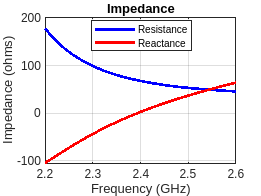


%% Antenna Analysis 

% Define frequency range 
freqRange = linspace(2.2e9, 2.6e9, 21);
figure;
impedance(antennaObject, freqRange)

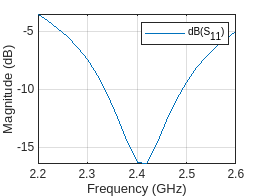

% sparameter
figure;
s = sparameters(antennaObject, freqRange); 
rfplot(s)

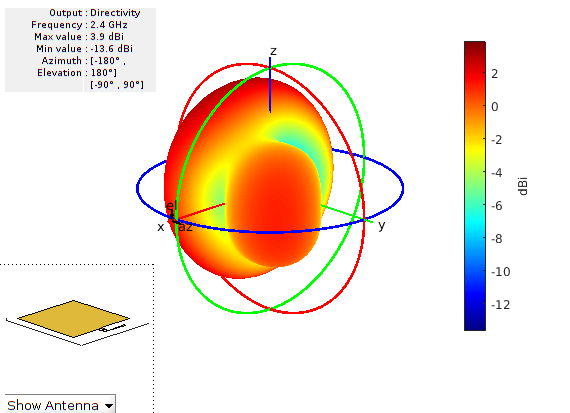

% pattern
figure;
pattern(antennaObject, F0)

If you need to know what type of things you can do with an antennaObject type run the following command:

methods(antennaObject)

Methods for class invertedFcoplanar:

EHfields           copy               feedCurrent        invertedFcoplanar  msiwrite           patternElevation   save               stlwrite           
axialRatio         current            get                memoryEstimate     optimize           rcs                set                vswr               
beamwidth          design             impedance          mesh               pattern            resultsParser      show               
charge             efficiency         info               meshconfig         patternAzimuth     returnLoss         sparameters        

Methods of invertedFcoplanar inherited from handle.



To put it on a PCB first run the below commands.

pcbAntenna = pcbStack(antennaObject)

pcbAntenna =   pcbStack with properties:

              Name: 'Coplanar Inverted-F'
          Revision: 'v1.0'
        BoardShape: [1×1 antenna.Rectangle]
    BoardThickness: 0.0013
            Layers: {[1×1 antenna.Polygon]}
     FeedLocations: [0 0.0361 1]
      FeedDiameter: 6.9396e-04
      ViaLocations: []
       ViaDiameter: []
      FeedViaModel: 'strip'
       FeedVoltage: 1
         FeedPhase: 0
         Conductor: [1×1 metal]
              Tilt: 0
          TiltAxis: [1 0 0]
              Load: [1×1 lumpedElement]


show(pcbAntenna)

The pcbAntenna object is a pcbStack object. So what these commands did was load the antenna's geometry onto a pcbStack object.

You can view any of the properties within the pcbStack object with the . operator like below.

pcbAntenna.Conductor

ans =   metal with properties:

            Name: 'PEC'
    Conductivity: Inf
       Thickness: 0

For more materials see catalog
